%{
Name: Cooling Curve Approximation
Author: Evan Scheuritzel
Version: 1.0
Purpose: determine change in temperature and total thermal exposure.
Input: none
Output: One graph with temperature, one with rate of tempeture change, and
another with temperature and total cold exposure.
%}

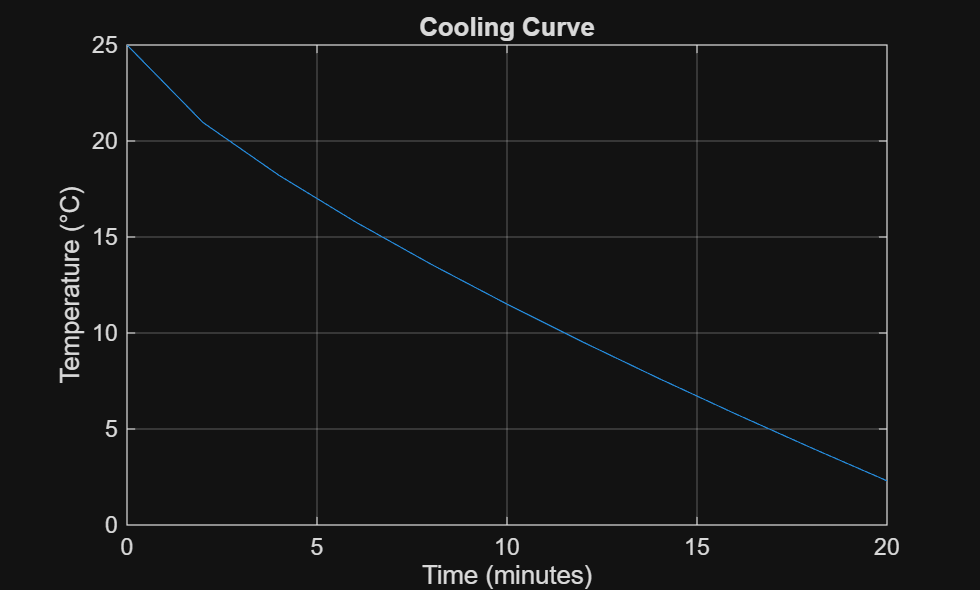

clear
% temperature will be measured every 2 miuntes
t = 0:2:20;
Temp = -2.4.*t.^.75 + 25;
plot(t,Temp)
xlabel('Time (minutes)');
ylabel('Temperature (°C)');
title('Cooling Curve');
grid on;

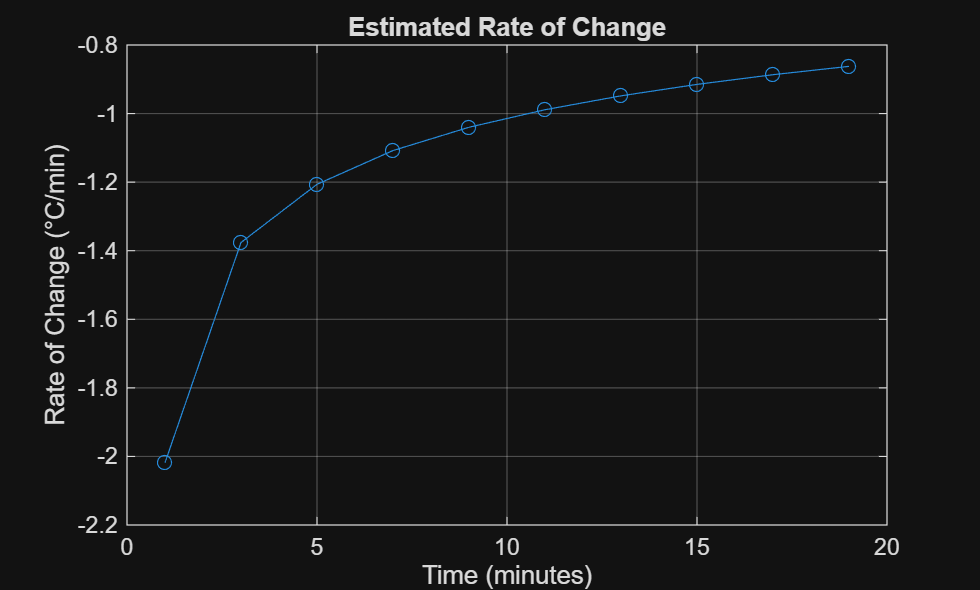

% estimate the rate of change using finite differences and plot it
dt = diff(t);                 % time intervals (should be constant 2)
dT = diff(Temp);              % temperature differences
rate = dT ./ dt;              % finite difference rate (°C per minute)

% For plotting, associate rates with midpoints of time intervals
t_mid = t(1:end-1) + dt/2;

figure;
plot(t_mid, rate, '-o');
xlabel('Time (minutes)');
ylabel('Rate of Change (°C/min)');
title('Estimated Rate of Change');
grid on;

% estimate total thermal exposure using area under curve (AUC) via trapezoidal rule
% Use the original time vector t and Temp
AUC = trapz(t, Temp);  % area in degree-minutes

% Also compute cumulative AUC at each time point for plotting
cumAUC = cumtrapz(t, Temp);

% Display result in command window
fprintf('Total thermal exposure  from t=%.1f to %.1f min: %.4f °C·min\n', t(1), t(end), AUC);

Total thermal exposure  from t=0.0 to 20.0 min: 241.3917 °C·min


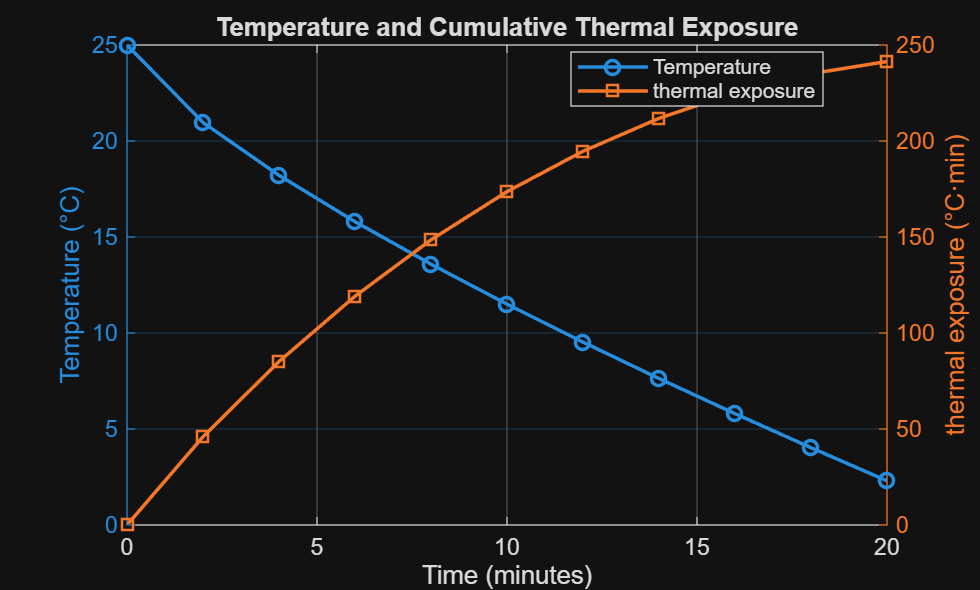


% Plot cumulative AUC on same figure as temperature with a second y-axis
figure;
yyaxis left
plot(t, Temp, '-o', 'LineWidth', 1.5);
ylabel('Temperature (°C)');
xlabel('Time (minutes)');
title('Temperature and Cumulative Thermal Exposure');
grid on;

yyaxis right
plot(t, cumAUC, '-s', 'LineWidth', 1.5);
ylabel('thermal exposure (°C·min)');
legend('Temperature','thermal exposure','Location','best');